# Triple Omniwheel

Copyright 2018 The MathWorks, Inc.

## Kinematic Model

This vehicle has 3 omniwheels located radially around a circular body. Since there are 3 independently actuated wheels, the vehicle has full motion control in all degrees of freedom, with unique solutions.

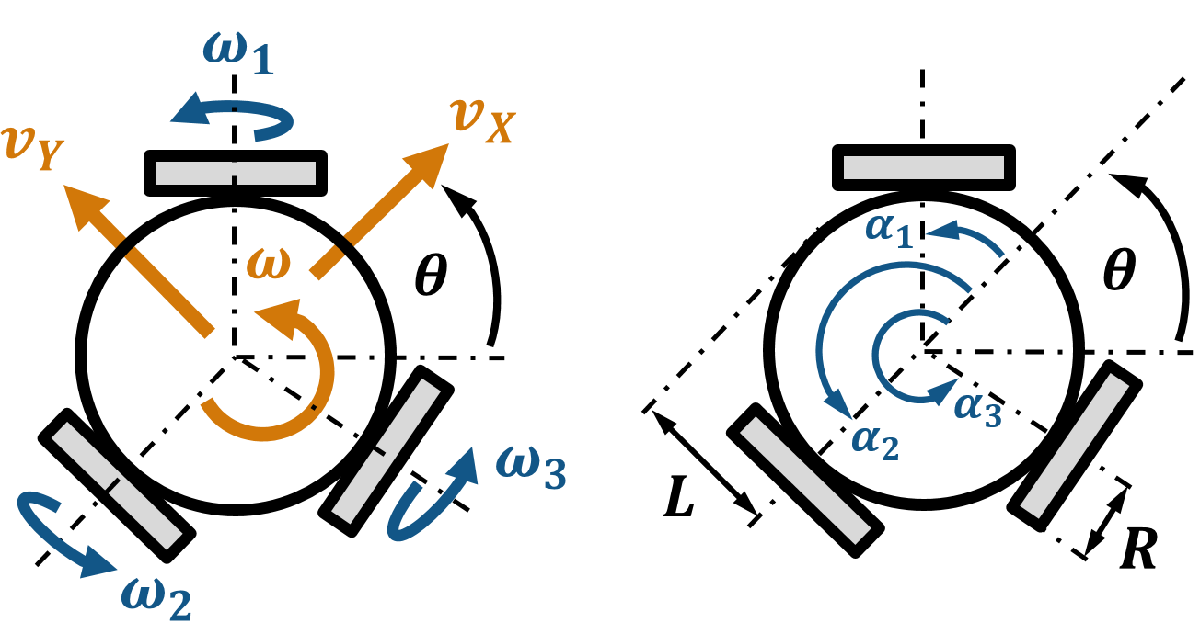

**Inputs:**

- Wheel speeds $\left\lbrack \omega_1 ;\omega_2 ;\omega_3 \right\rbrack$, in rad/s

**Outputs**

- Linear velocities$v_X$ and $v_Y$, in m/s

- Angular velocity $\omega$, in rad/s

**Forward Kinematics**

The forward kinematics can be expressed in matrix form as follows.


$${\left[\begin{array}{c}
v_X \\
v_Y \\
\omega 
\end{array}\right]}=\frac{R}{3}{\left[\begin{array}{ccc}
\sin {\left(\alpha_1 \right)} & \sin {\left(\alpha_2 \right)} & \sin {\left(\alpha_3 \right)}\\
-\cos {\left(\alpha_1 \right)} & -\cos {\left(\alpha_2 \right)} & -\cos {\left(\alpha_3 \right)}\\
-1/L & -1/L & -1/L
\end{array}\right]}{\left[\begin{array}{c}
\omega_1 \\
\omega_2 \\
\omega_3 
\end{array}\right]}=\mathit{\mathbf{M}}{\left[\begin{array}{c}
\omega_1 \\
\omega_2 \\
\omega_3 
\end{array}\right]}$$


**Inverse Kinematics**

To calculate inverse kinematics, the forward kinematics matrix $\mathit{\mathbf{M}}$ can be inverted to give the following equation.


$${\left[\begin{array}{c}
\omega_1 \\
\omega_2 \\
\omega_3 
\end{array}\right]}  ={\mathit{\mathbf{M}}}^{-1} {\left[\begin{array}{c}
v_X \\
v_Y \\
\omega 
\end{array}\right]}$$


## MATLAB Usage

Create a `TripleOmniwheel` object

wheelRadius = 0.1; 			% Wheel radius [m]
robotRadius = 0.25; 			% Robot radius [m]
wheelAngles = [0, 2*pi/3, -2*pi/3]; 	% Wheel angles [rad]
vehicle = TripleOmniwheel(wheelRadius,robotRadius,wheelAngles)

vehicle =   TripleOmniwheel with properties:

    wheelRadius: 0.1000
    robotRadius: 0.2500
    wheelAngles: [0 2.0944 -2.0944]


Solve forward kinematics

w = [1; -0.25; 0.5]; % Wheel speeds [w1; w2; w3]	
vel = forwardKinematics(vehicle,w)

vel =    -0.0217
   -0.0292
   -0.1667


Solve inverse kinematics

velRef = [-0.5; 0; 1.5]; % Body speeds [vx; vy; w]
w = inverseKinematics(vehicle,velRef)

w =    -3.7500
  -12.4103
    4.9103


Get the forward and inverse kinematics matrices

M = getForwardMatrix(vehicle)

M =          0    0.0289   -0.0289
   -0.0333    0.0167    0.0167
   -0.1333   -0.1333   -0.1333


Minv = getInverseMatrix(vehicle)

Minv =     0.0000  -20.0000   -2.5000
   17.3205   10.0000   -2.5000
  -17.3205   10.0000   -2.5000


Change a parameter and update the kinematics matrices. Rerun the previous section to see the different matrices.

vehicle.wheelRadius = 0.05;
computeMatrices(vehicle);

Reference examples:

- [Discrete-time kinematic simulation](matlab:edit mrsTripleOmniDiscrete)

- [Continuous-time kinematic simulation](matlab:edit mrsTripleOmniContinuous)

## Simulink Usage

Simulink blocks are in the **Kinematic Models > Triple Omniwheel** section of the [block library](matlab:mobileRoboticsLib).

- Use the **Triple Omniwheel Forward Kinematics** and **Triple Omniwheel Inverse Kinematics** blocks to convert between body velocities and wheel velocities.

- Use the **Triple Omniwheel Simulation** block to simulate the pose given wheel speeds as inputs. You can configure the initial pose and simulation sample time.

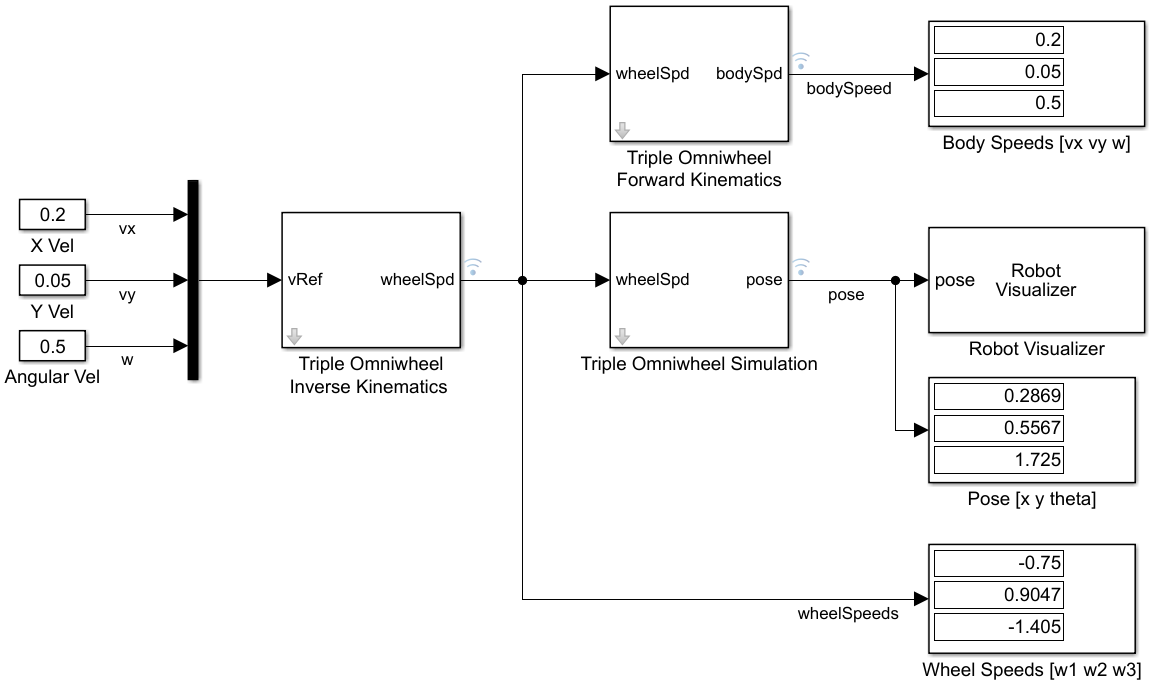

Reference example:

- [Triple omniwheel kinematic simulation](matlab:mrsTripleOmniModel)